## **Autonomus Algorithm Development**

This example model utilizes the variable planner and scenario simulation to plan and simulate an autonomous underwater vehicle mission. The model is comprised of three main components: Scheduler, Path Planner and Scenario Simulation

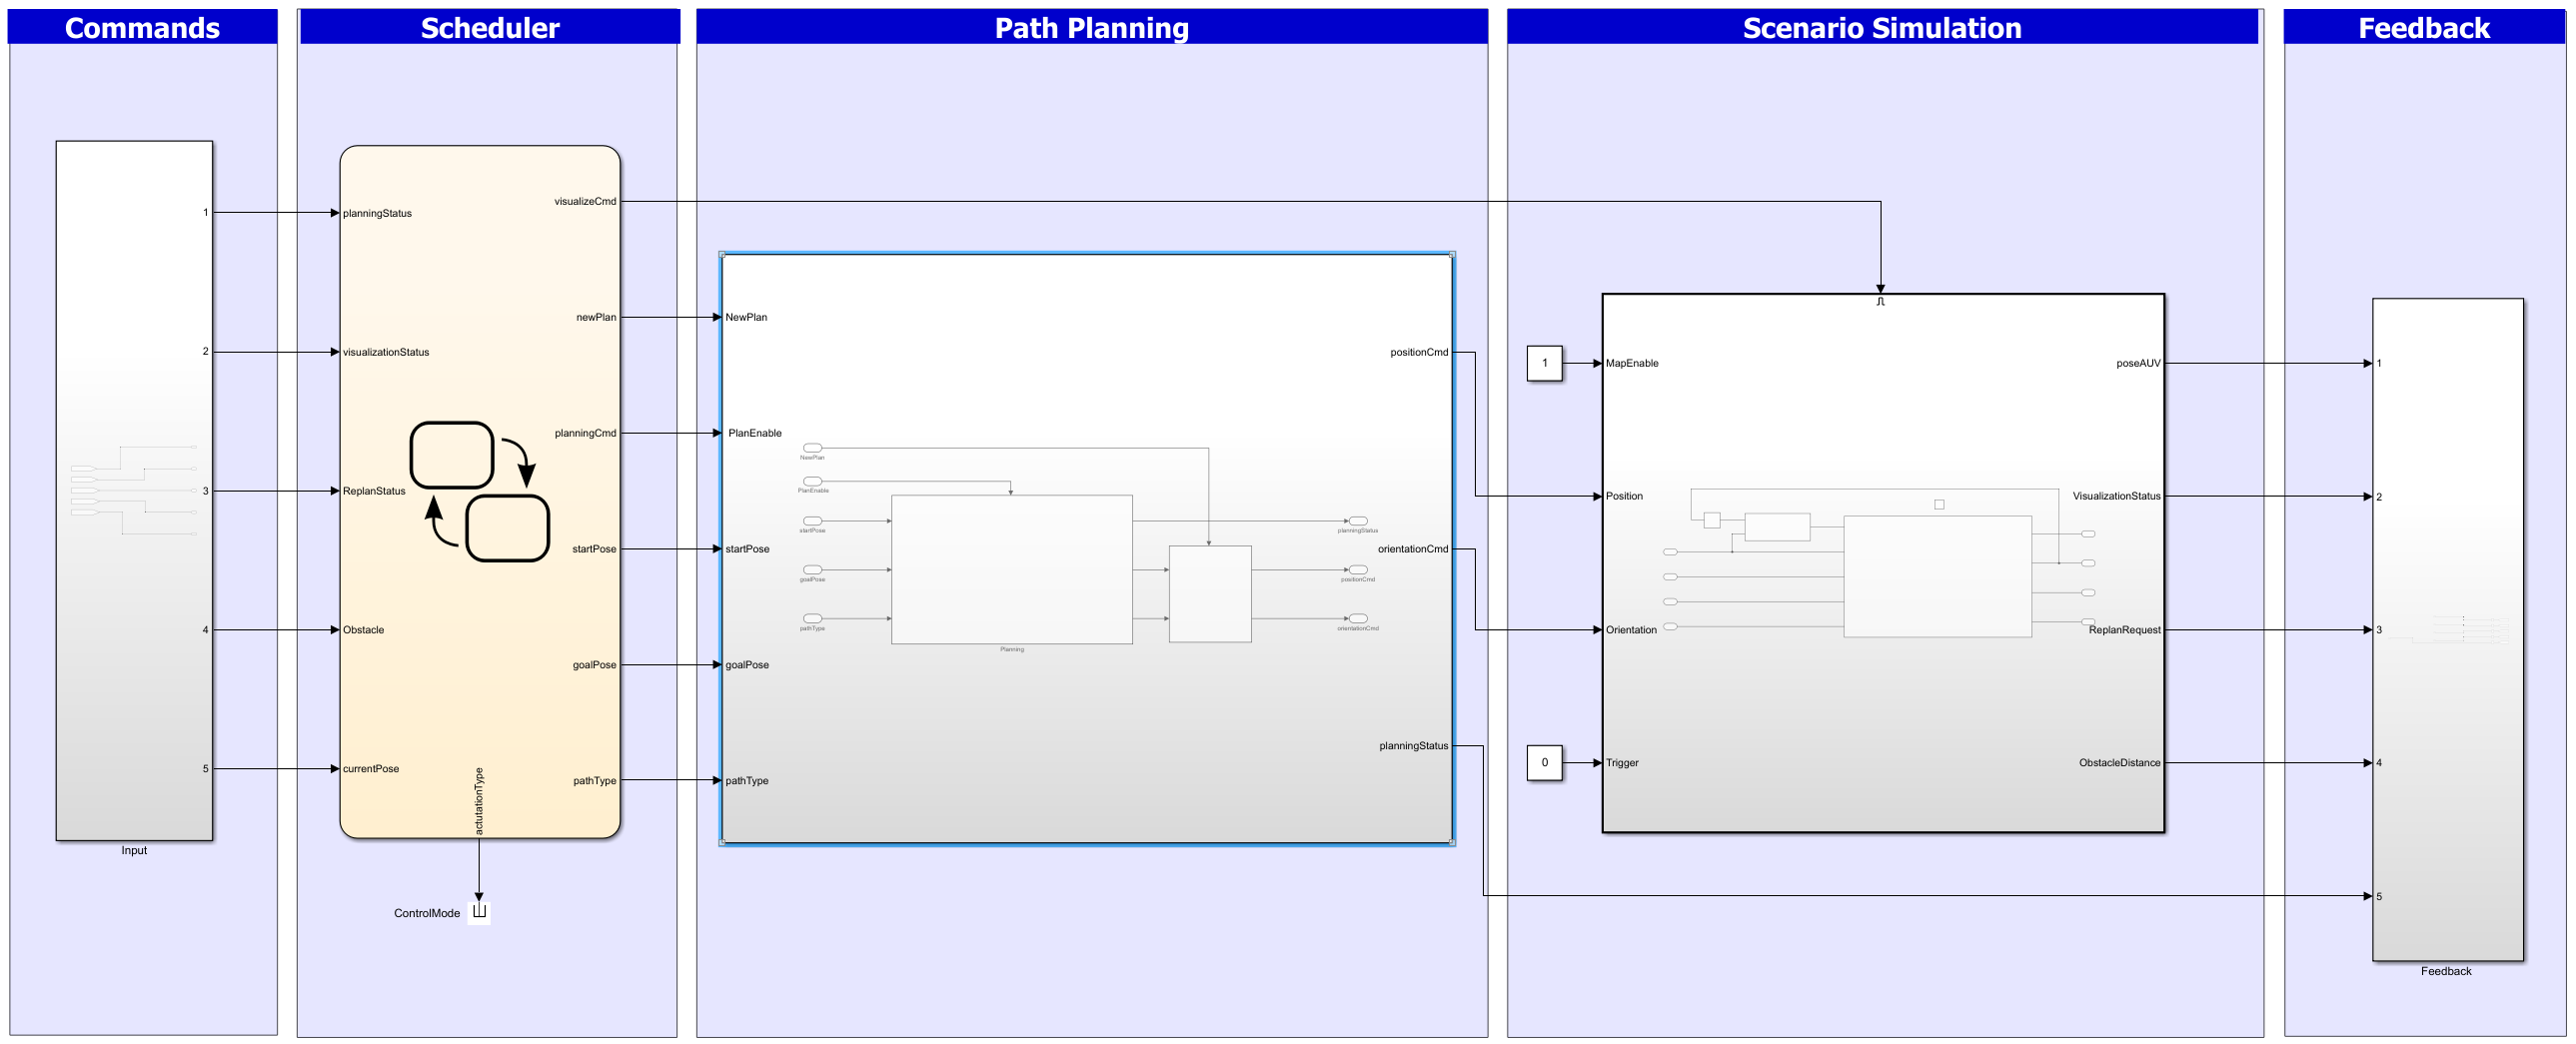

open_system("multiModePlanner")

**Scheduler**

The schedule provide a sequence of tasks based on the various stages of the autonomous mission. It provides the inputs to the path planner based on the current task and initiates the simulation once the a set of waypoints have been generated. Each stage will auto populate the start and goal poses and will also select the desired path type. The Scheduler is implemented using StateFlow.

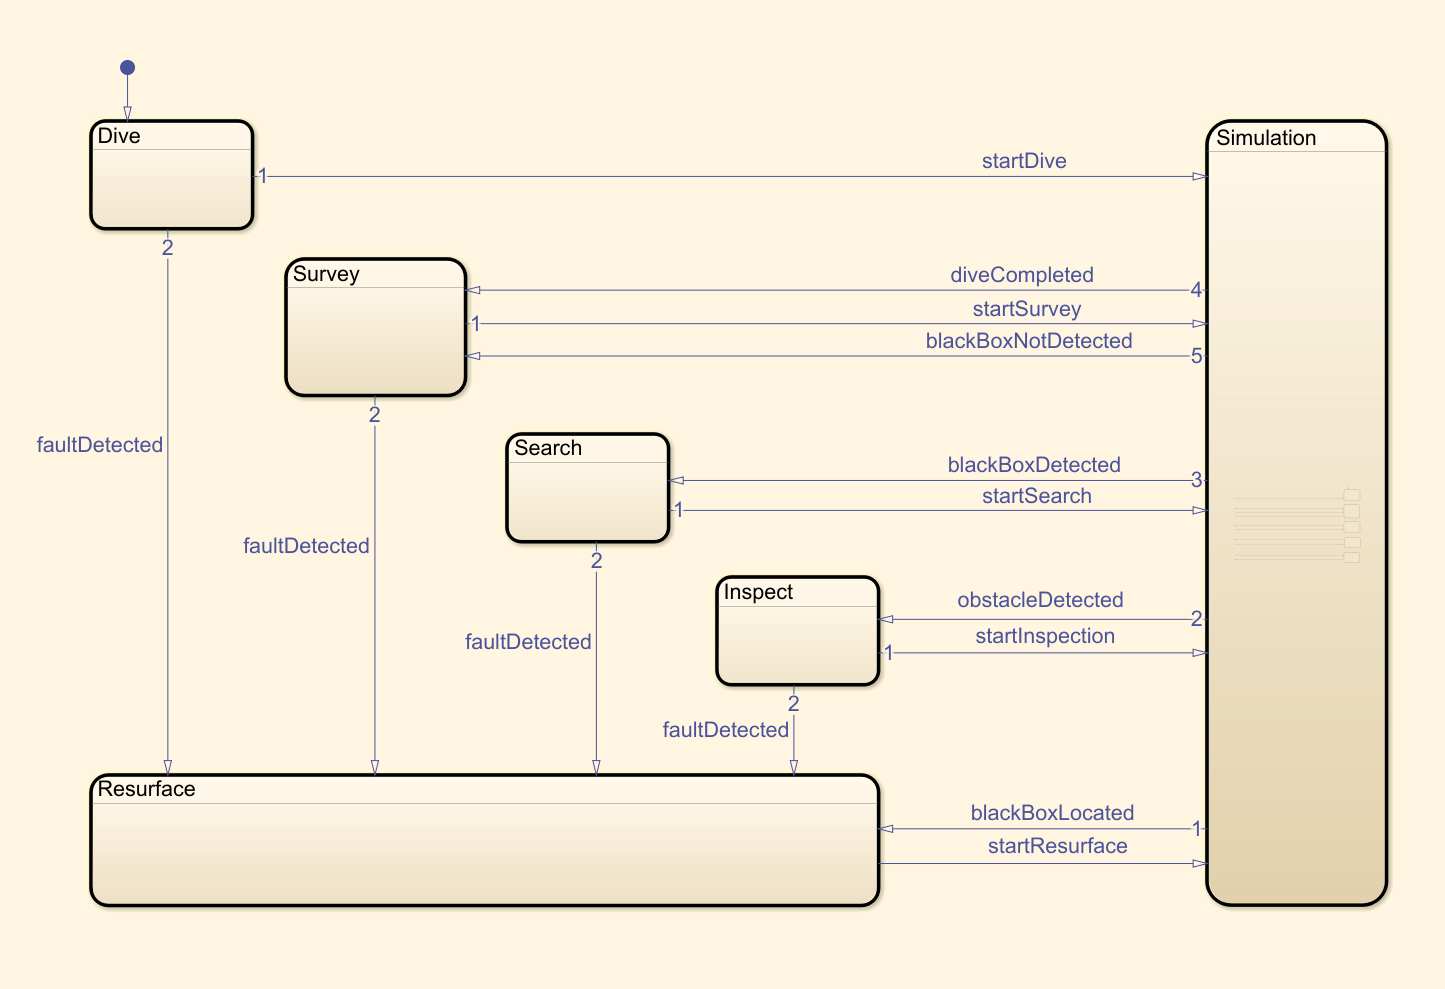

The mission is subdivided into five sections: 

Dive: Manuver to the required depth using a helical motion to begin the survey.

Survey: Follow a lawn mover style path to map the seabed while listening for a ping from the blackbox. If ping is not received, navigate to a new start location and continue surveying. 

Search: Navigate to a coordinate above the expected blackbox position and move closer to the seabed using a helical motion.

Inspect: In case of obstacles, generate an alternative tragectory to move closer to the seabed using an over actuated motion.

Resurface: In case of a fault or if the blackbox is found, resurface immediately. 

open_system("multiModePlanner/Scheduler Subsystem")

**Path Planner**

The path planner generates a set of waypoints to navigate based on the current task. The path planner has three modes of operation based on the path type input. It also takes start and goal postions as input. Once a path has been generated, it provide postion and orientation vectors to the scenario simulation.

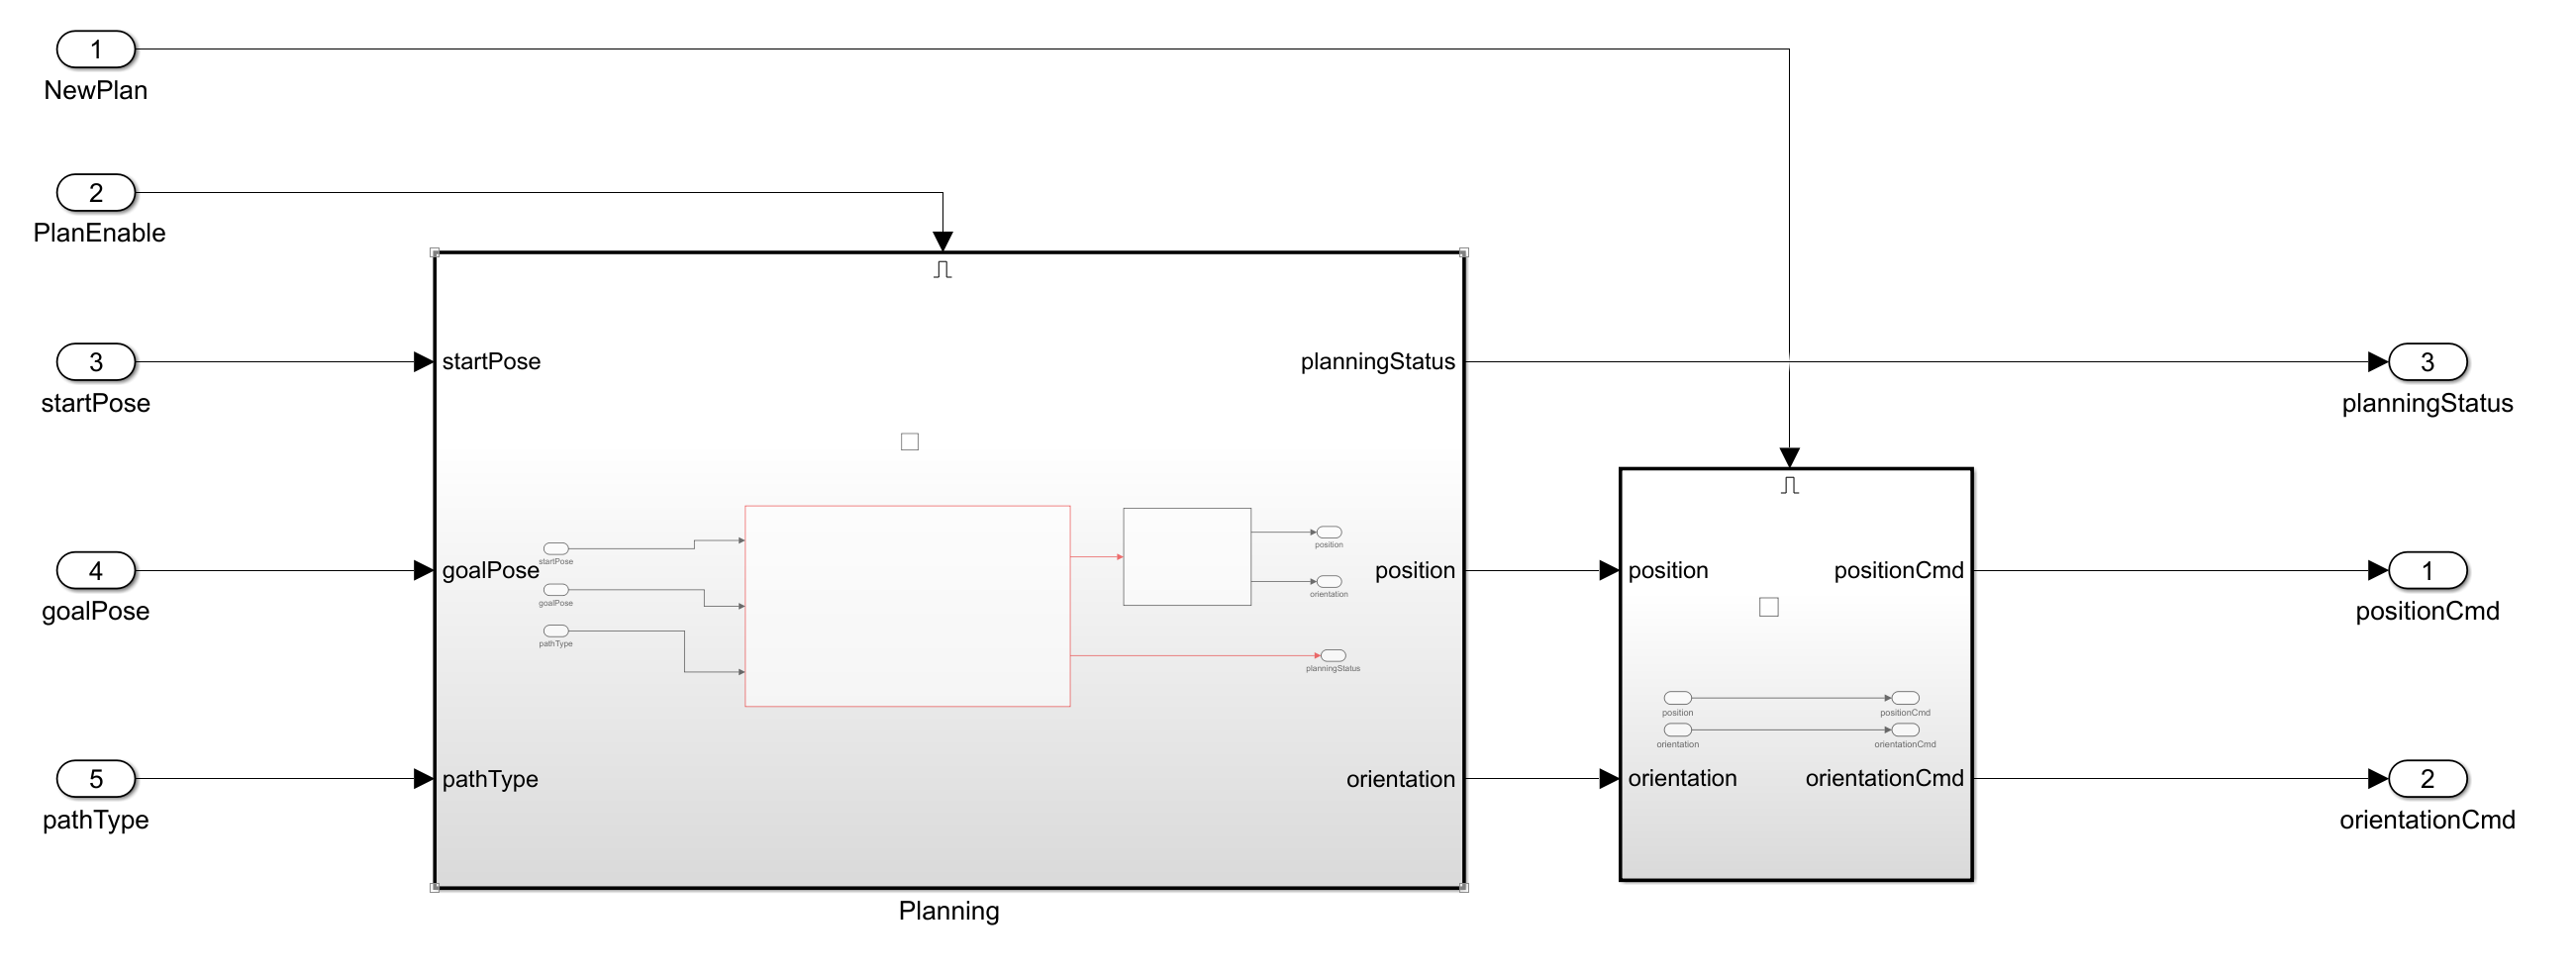

Modes of operation (pathType)

1: Lawn mover style path that generated using a MATLAB executable generated using a C++ algorithm.

2: Inefficient over acutated straight line path.  

3: Efficient helical path.

open_system("multiModePlanner/Planning Subsystem")

**Scenario Simulation**

The scenario simulation uses a scenario to simulate the tragectory followed by the underwater vehicle while providing INS and Sonar sensor values to localize the vehicle and generate a map of the seabed. The sensor models can be modified realise the sensor noises such as orientation and postion inaccuracies. 

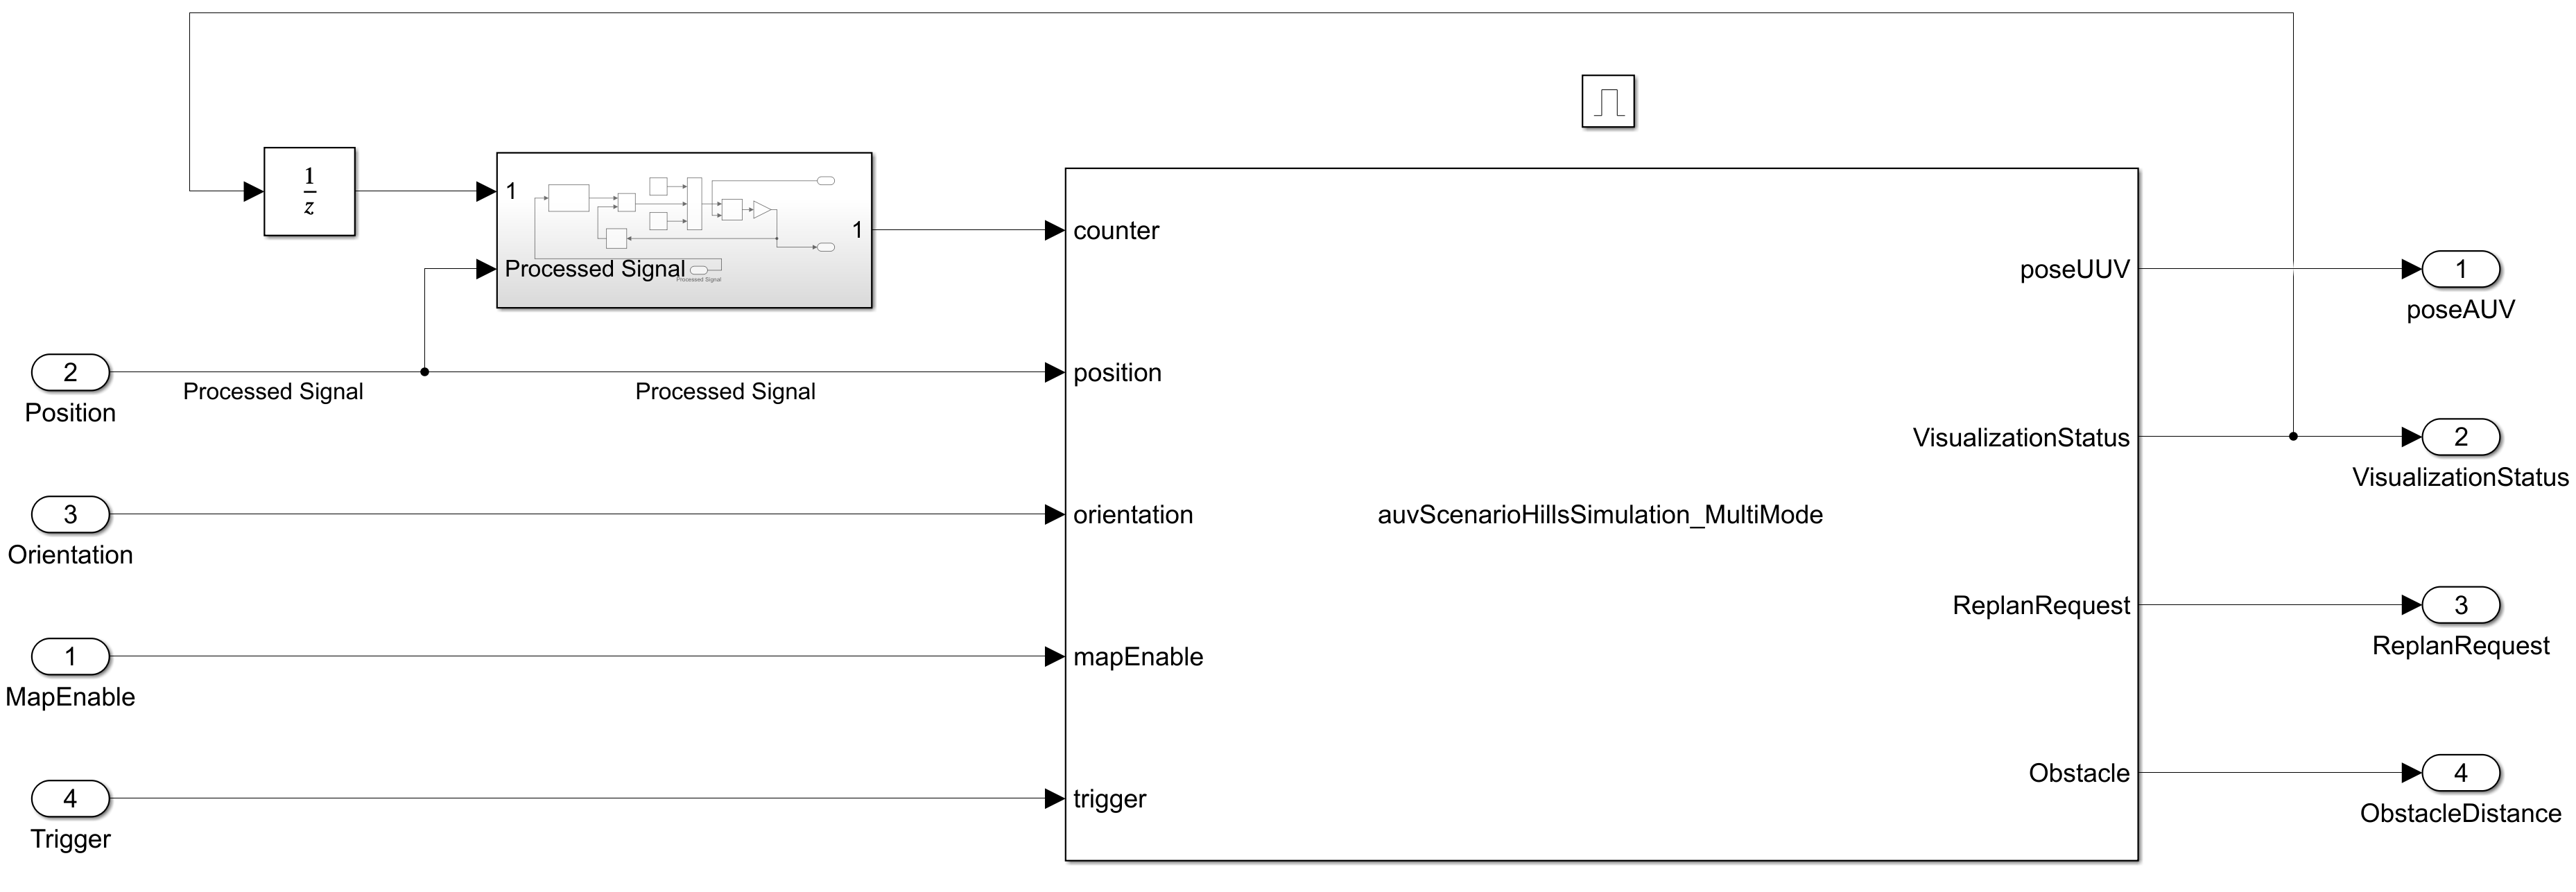

open_system("multiModePlanner/Simulation Subsystem")